# Part 4: Descriptive Statistics

[*Return to introduction*](matlab: edit S1_Introduction.mlx)

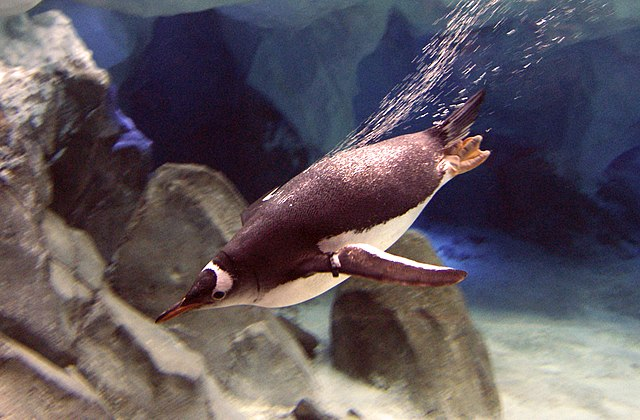

A gentoo penguin using its flippers to [dive](https://commons.wikimedia.org/wiki/File:Gentoo_Penguin._swimming_(10909435215).jpg). 

Make sure you've gone through the previous live scripts in this module. If `penguins` is no longer in your workspace, this block of code will get everything set up for this activity: 

filename = "penguins.csv";
penguins = readtable(filename);
penguins.species = categorical(penguins.species);
penguins.island = categorical(penguins.island);
penguins.sex = categorical(penguins.sex);
penguins1 = rmmissing(penguins);
chinstrap = penguins1(penguins1.species == "Chinstrap",:);
gentoo = penguins1(penguins1.species == "Gentoo",:); 
adelie = penguins1(penguins1.species == "Adelie",:);

## Overview of descriptive statistics

Don't worry, you already know a lot of [descriptive statistics](https://www.mathworks.com/help/matlab/descriptive-statistics.html)! 

For example, a few statistics we might use to describe our data are: 

- the [**minimum**](https://www.mathworks.com/help/matlab/ref/min.html) or [**maximum**](https://www.mathworks.com/help/matlab/ref/max.html) value of your data set (as a bonus, if you subtract the min from the max you'll get the [**range**](https://www.mathworks.com/help/stats/range.html) of your dataset)

- the [**mean**](https://www.mathworks.com/help/matlab/ref/mean.html) value (average of your data) 

- the [**median**](https://www.mathworks.com/help/matlab/ref/median.html) value (midpoint of your data if you order all data points in numerical order)

- the [**mode**](https://www.mathworks.com/help/matlab/ref/mode.html) value (the value that appears most often in your data set) 

- the [**standard deviation**](https://www.mathworks.com/help/matlab/ref/std.html) of your data (a measure of the spread of your distribution, or how far the majority of values tend to lie from the mean)

Lucky for us, there's a built-in MATLAB® function for each of these methods! 

First, let's pull back up the histogram so we can easily see how these statistics map onto it.

histogram(penguins1.flipper_length_mm)
xlabel("Flipper Length (mm)")
ylabel("Frequency")
title("Distribution of penguin flipper lengths")

Find the minimum flipper length in the population using` min()`:

min_flip = min(penguins1.flipper_length_mm) 

min_flip = 172

xline(min_flip, "LineWidth",5)

Find the maximum flipper length in the population using `max()`:

max_flip = max(penguins1.flipper_length_mm)

max_flip = 231

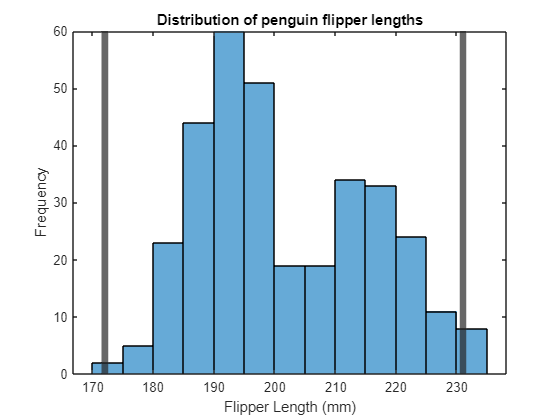

xline(max_flip, "LineWidth",5)

The minimum and maximum values have been plotted as vertical lines on our histogram. The built-in function [`xline()`](https://www.mathworks.com/help/matlab/ref/xline.html) creates a vertical line at a given constant value of x. 

Looking at this data, we can say that all of our flipper length values lie between 172 and 231 mm (this is the range of our dataset). 

Next, let's find the mean, median, and mode of our dataset: 

histogram(penguins1.flipper_length_mm, "EdgeColor","none") % you can remove the edges by utilzing the "EdgeColor" option
xlabel("Flipper Length (mm)")
ylabel("Frequency")
title("Distribution of penguin flipper lengths")
mean_flip = mean(penguins1.flipper_length_mm)

mean_flip = 200.9670

xline(mean_flip, "--")

median_flip = median(penguins1.flipper_length_mm)

median_flip = 197

xline(median_flip, ":", "LineWidth",1.5)
mode_flip = mode(penguins1.flipper_length_mm)

mode_flip = 190

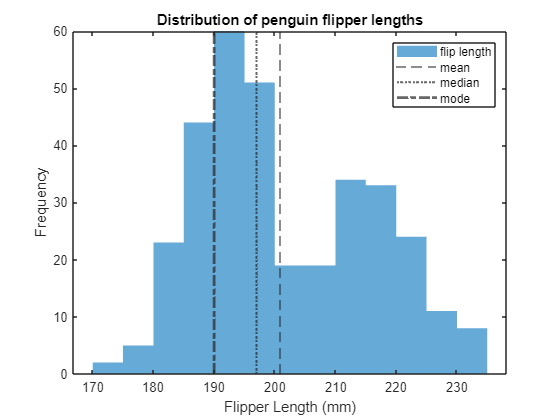

xline(mode_flip, "-.", 'LineWidth',2)
legend ("flip length", "mean", "median", "mode")

We plotted the mean, median, and mode with slightly different line styles so that we can visualize them on our histogram. Note that the mode is at 190 mm, which you'll notice is the highest ('most frequent') value on the histogram. 

Finally, we can compute the standard deviation using `std()`: 

std_flip = std(penguins1.flipper_length_mm)

std_flip = 14.0158

We can therefore say that the majority of flipper length values within our population tend to lie within 14 mm from the mean, which is 201 mm. Most penguins have a flipper length between 187 mm and 215 mm. 

##  Exercise: Use descriptive statistics to summarize data from one species

Pick your favorite penguin species and characteristic and calculate these descriptive statistics. What do they tell you about your data? Hint: if you pick Chinstrap penguins and want to describe the population's body weight, to plot the histogram and then find the minimum body mass you would run: 

Your code here: 

**A:  Plot the histogram for comparison (make sure to add labels and a title). **

**B: Find the minimum value.  **

**C: Find the maximum value. **

**D: Find the average of the dataset (mean). **

**E: Find the midpoint of the ordered dataset (median). **

**F: Find the most frequent value in the dataset (mode). **

**G: Find the standard deviation of your dataset. **

**BONUS: What's the range of this dataset?**

### Exercise Answers: 

% Example code if you chose Adelie penguins and body mass.

histogram(adelie.body_mass_g) % A
xlabel("Body mass (g)")
ylabel("Frequency")
title("Distribution of body mass in Adelie population")
min_admass = min(adelie.body_mass_g) % B
max_admass = max(adelie.body_mass_g) % C
mean_admass = mean(adelie.body_mass_g) % D
median_admass = median(adelie.body_mass_g) % E
mode_admass = mode(adelie.body_mass_g) % F
std_admass = std(adelie.body_mass_g) % G
rng_admass = range(adelie.body_mass_g) % BONUS

##  Further resources: 

- Penn State has a statistics resource called [STAT 200](https://online.stat.psu.edu/stat200/) which has a lot more information on statistics topics covered here. 

- Learn how to calculate multiple descriptive statistics at one using the MATLAB function [`grpstats()`](https://www.mathworks.com/help/stats/grpstats.html). 

[*Continue to next section (Predictive modeling)*](matlab: edit S5_Predictive_modeling.mlx)

[*Return to introduction*](matlab: edit S1_Introduction.mlx)